# Лабораторная №1

Даны следующие уравнения:


$$3x^4+4x^3-12x^2-5=0$$



$$ln(x)+(x+1)^3=0$$


f1 = @(x) 3*x.^4+4*x.^3-12*x.^2-5;
f2 = @(x) log(x)+(x+1).^3;

**Предварительная оценка:**

Используем теорему о верхней границе положительных корней полинома для уравнения 1:


$$\alpha =1+\sqrt[m]{\frac{a^{\prime } }{a_0 }}=3$$


Аналогично, $\beta =-3$

Построим график:

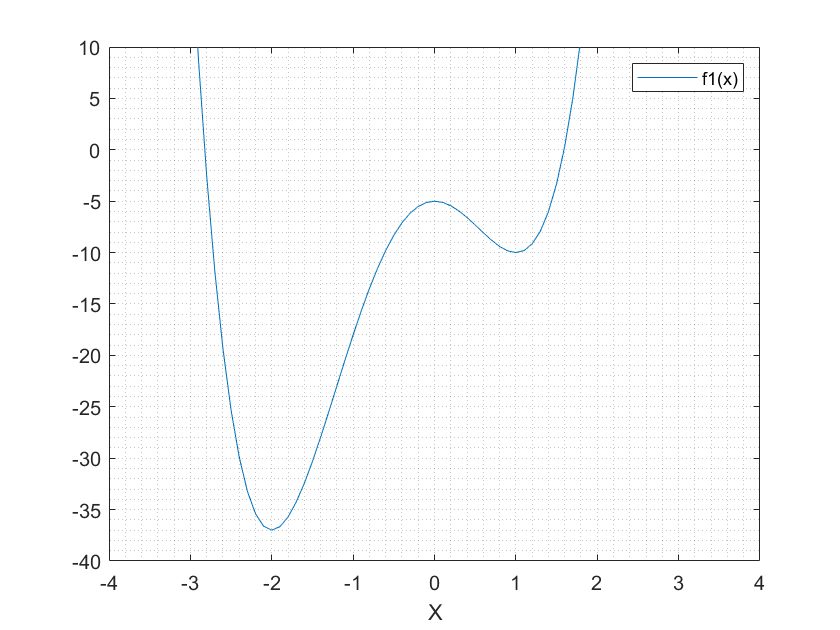

x = -4:0.1:4;
plot(x, f1(x));
grid minor
xlabel('X');
legend('f1(x)');
xlim([-4 4])
ylim([-40 10])

Теорема о верхней границе положительных корней дала адекватные результаты. Для поиска корней можно взять отрезок [-3; 3], разбитый с шагом 1.

%Задаем массив отрезков
delta = [-3, -2, -2, -1, -1, 0,  0, 1, 1, 2];

Для 2-го уравнения применим графический метод отделения корней:

x = -3:0.1:1;
plot(x, f2(x));

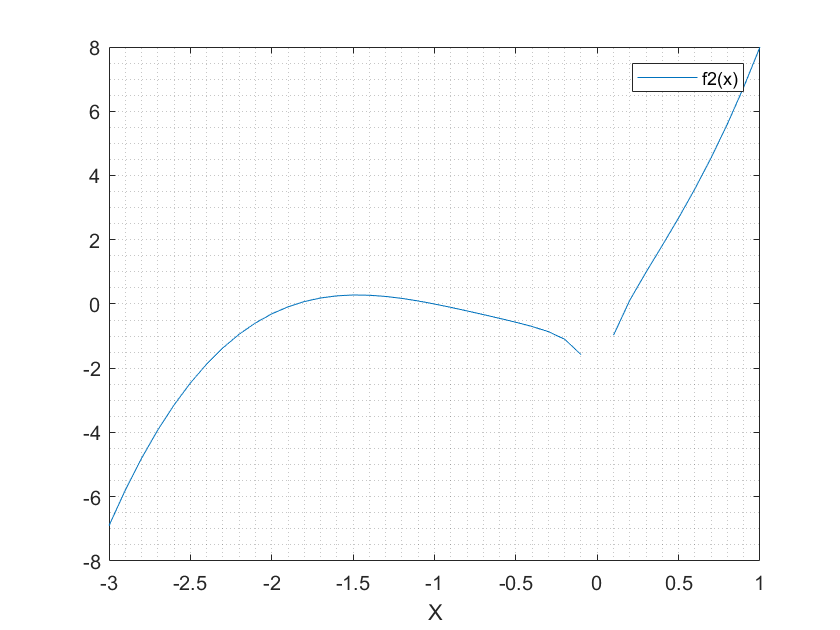

grid minor
xlabel('X')
legend('f2(x)')

Визуально корни находятся на отрезке  [-2.5; 1]:

delta2 = [-2, -1.5, -1.5, -1, 0.15, 0.5];

**Методы решения:**

- Метод половинного деления;

- Метод простых итераций.

Метод 1 реализован в функции double_del, функция edsolve предназначена для построения графика зависимости количества итераций от точности. 

### Решение первого уравнения методом половинного деления:

%Значение ошибки
e = 0.00001;
 

out = [];
N = 0;
for i = 1:2:length(delta)
    lout = double_del(delta(i), delta(i+1), e, f1);
    if lout(1) ~= 0
        out = [out, lout(2)];
        N = N + lout(1);
    end
end
x = delta(1):0.01:delta(length(delta));
figure
plot(x, f1(x))
hold on, grid minor
xlabel('X');
ylabel('Y');
plot(out, 0, 'marker', '*', 'Color', 'red')
legend('f1(x)', 'roots')
disp(out)

   -2.8239    1.5921



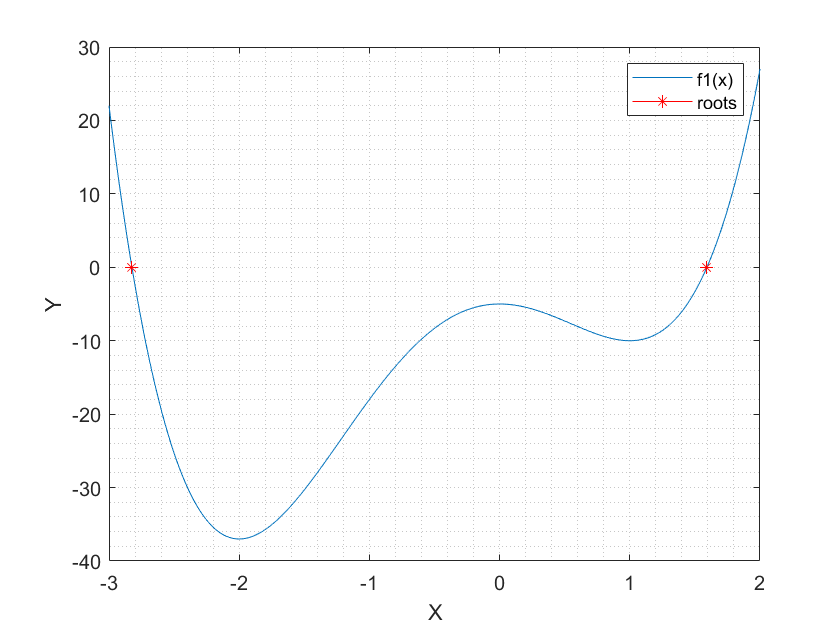

saveas(gcf, 'roots1.png')

**Построение графика зависимости количества итераций от ошибки для 1-го уравнения**

param — параметры для построения графика, первое окно — максимальная погрешность, второе — минимальное, третье — шаг.

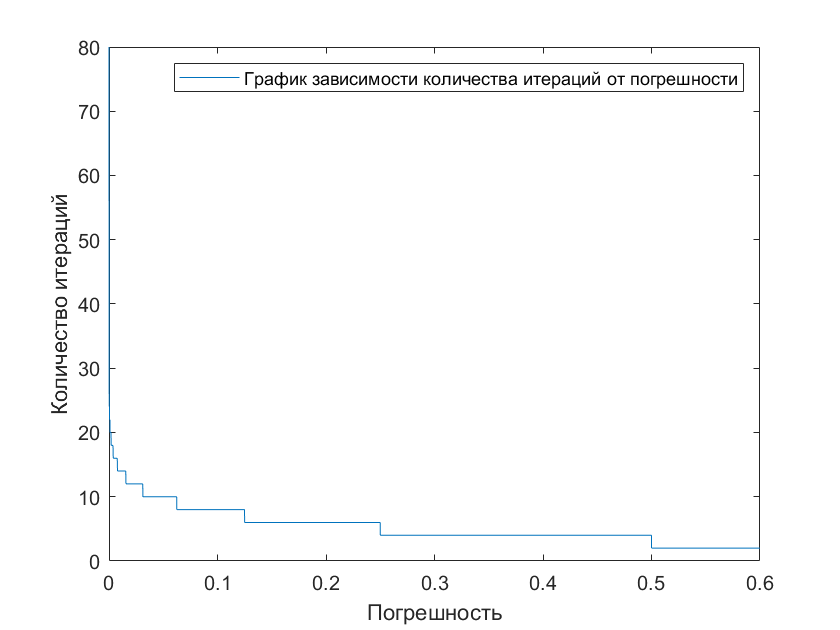

param = [0.6,1e-12,0.00001];
 
matr = edsolve(delta, f1, param(2), param(1), param(3), 1);
figure
plot(matr(1, :), matr(2, :))
xlabel('Погрешность');
ylabel('Количество итераций');
legend('График зависимости количества итераций от погрешности');
saveas(gcf, 'err11.png')

**Построение зависимости количества итераций от начального приближения для 1-го уравнения**

В качестве параметра начального приближения является длинна отрезка.

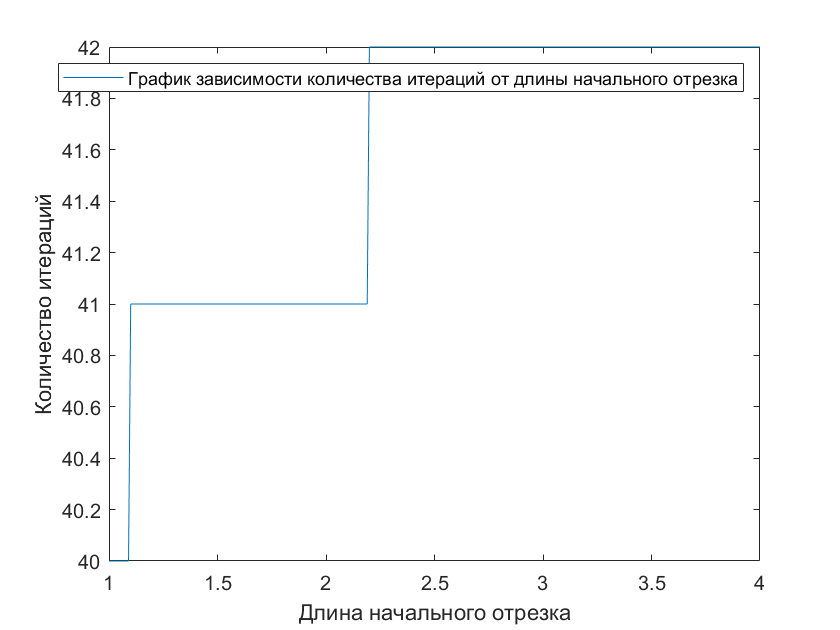

 
param = [-3,
    4,
    1,
    0.01,
    1e-12];
matr = prdsolve(param(1), f1, param(2), param(3), param(4), param(5), 1);
figure
plot(matr(1, :), matr(2, :))
xlabel('Длина начального отрезка');
ylabel('Количество итераций');
legend('График зависимости количества итераций от длины начального отрезка');
saveas(gcf, 'len11.png')

### Решение второго уравнения методом половинного деления

%Значение ошибки
e = 1e-12;
 

out = [];
N = 0;
for i = 1:2:length(delta2)
    lout = double_del(delta2(i), delta2(i+1), e, f2);
    if lout(1) ~= 0
        out = [out, lout(2)];
        N = N + lout(1);
    end
end
x = delta2(1):0.01:delta2(length(delta2));
figure
plot(x, f2(x))

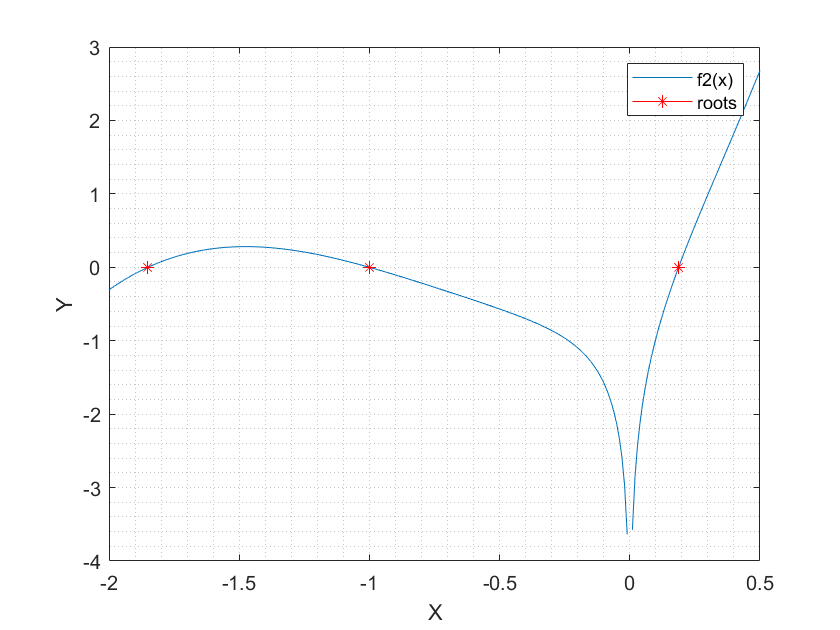

hold on, grid minor
xlabel('X');
ylabel('Y');
plot(out, 0, 'marker', '*', 'Color', 'red')
legend('f2(x)', 'roots')
saveas(gcf, 'roots2.png')

disp(out)

   -1.8507   -1.0000    0.1874



**Построение графика зависимости количества итераций от ошибки для 2-го уравнения**

param — параметры для построения графика, первое окно — максимальная погрешность, второе — минимальное, третье — шаг.

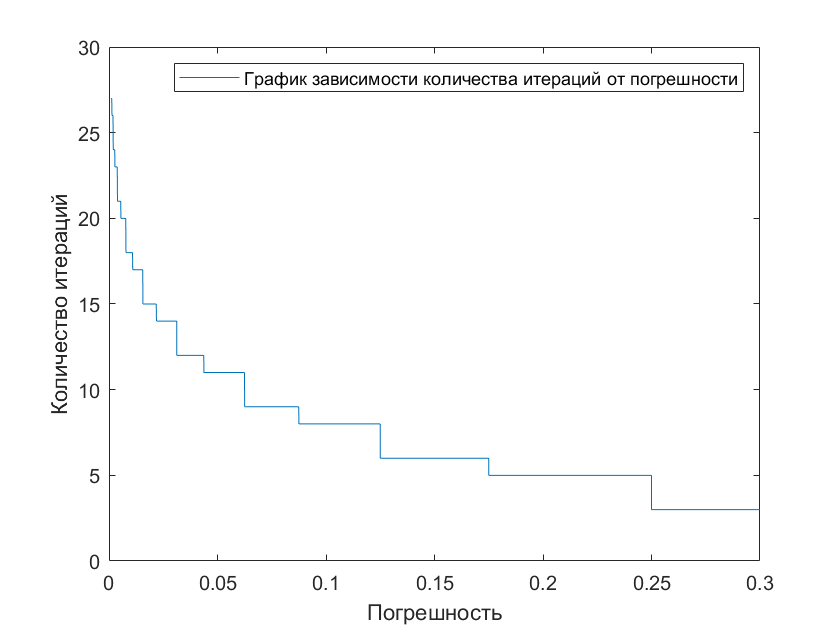

param = [0.3,0.001,0.000001];
 
matr = edsolve(delta2, f2, param(2), param(1), param(3), 1);
figure
plot(matr(1, :), matr(2, :))
xlabel('Погрешность');
ylabel('Количество итераций');
legend('График зависимости количества итераций от погрешности');
saveas(gcf, 'error21.png')

**Построение зависимости количества итераций от начального приближения для 2-го уравнения**

В качестве параметра начального приближения является длинна отрезка.

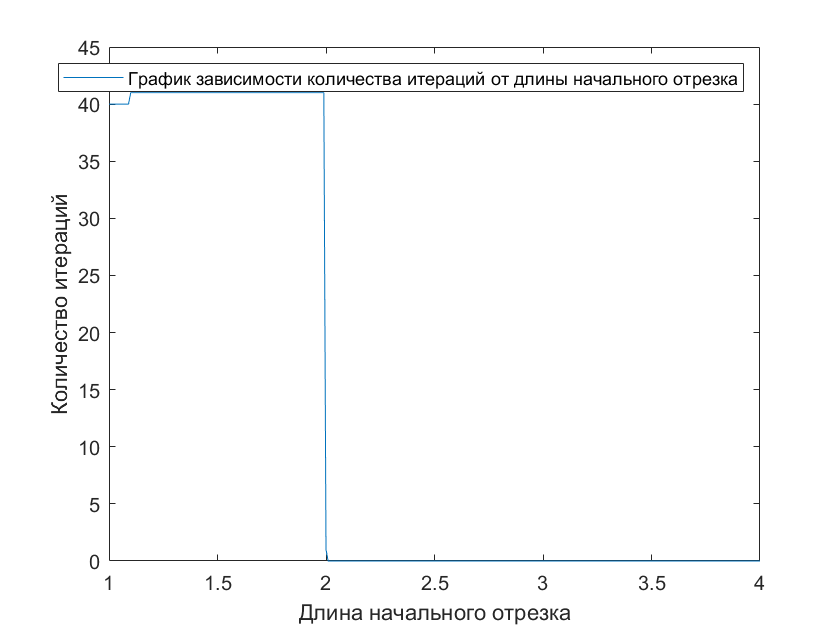

  
param = [-2,
    4,
    1,
    0.01,
    1e-12];
matr = prdsolve(param(1), f2, param(2), param(3), param(4), param(5), 1);
figure
plot(matr(1, :), matr(2, :))
xlabel('Длина начального отрезка');
ylabel('Количество итераций');
legend('График зависимости количества итераций от длины начального отрезка');
saveas(gcf, 'len21.png')

### Решение первого уравнения методом простых итераций

Уравнение $f(x) = 0
$ требуется привести к виду $x = \varphi(x)$. В частности


$$\varphi(x)=x-{\lambda}(x)f(x)$$


В качестве $\lambda(x)$ берется константа того же знака, что и производная в окрестности корня.

Формула итераций:


$$x_{i+1}=x_i-{\lambda}_0f(x_i)$$


%Значение ошибки
e = 1e-12;
 

out = [];
N = 0;
for i = 1:2:length(delta)
    lout = simple_iter(delta(i), e, f1);
    if lout(1) ~= 0
        out = [out, lout(2)];
        N = N + lout(1);
    end
end
x = delta(1):0.01:delta(length(delta));
figure
plot(x, f1(x))
hold on, grid minor
xlabel('X');
ylabel('Y');
plot(out, 0, 'marker', '*', 'Color', 'red')
legend('f1(x)', 'roots')

disp(out)

   -2.8239    1.5921



**Построение графика зависимости количества итераций от ошибки для 1-го уравнения**

param — параметры для построения графика, первое окно — максимальная погрешность, второе — минимальное, третье — шаг.

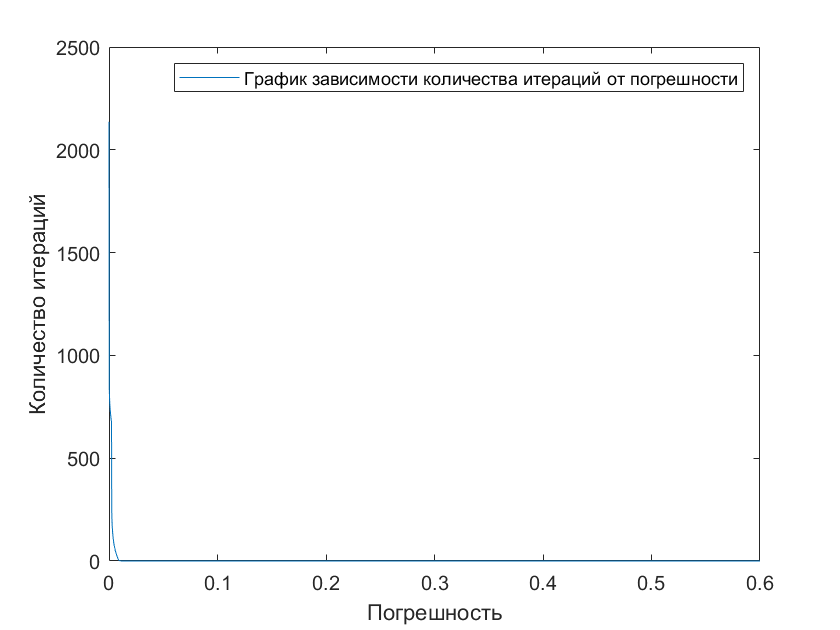

param = [0.6,1e-12,0.00001];
 
matr = edsolve(delta, f1, param(2), param(1), param(3), 2);
figure
plot(matr(1, :), matr(2, :))
xlabel('Погрешность');
ylabel('Количество итераций');
legend('График зависимости количества итераций от погрешности');
saveas(gcf, 'error12.png')

**Построение зависимости количества итераций от начального приближения для 1-го уравнения**

В качестве параметра начального приближения является длинна отрезка.

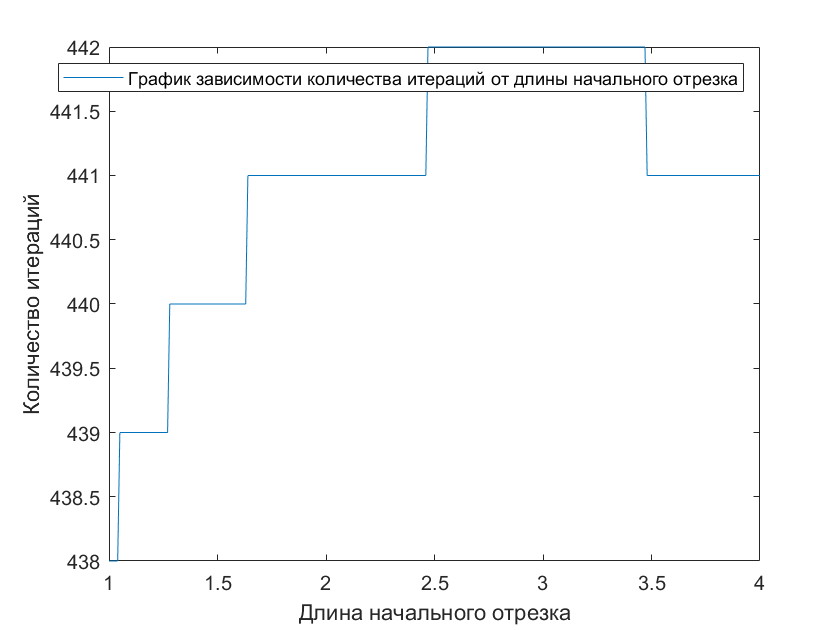

 
param = [-3,
    4,
    1,
    0.01,
    1e-12];
matr = prdsolve(param(1), f1, param(2), param(3), param(4), param(5), 2);
figure
plot(matr(1, :), matr(2, :))
xlabel('Длина начального отрезка');
ylabel('Количество итераций');
legend('График зависимости количества итераций от длины начального отрезка');
saveas(gcf, 'len12.png')

### Решение второго уравнения методом простых итераций

Формула итераций:


$$x_{i+1}=x_i-{\lambda}_0f(x_i)$$


%Значение ошибки
e = 1e-12;
 

out = [];
N = 0;
for i = 1:length(delta2)
    lout = simple_iter(delta2(i), e, f2);
    if lout(1) ~= 0 || lout(2) ~= 0
        out = [out, lout(2)];
        N = N + lout(1);
    end
end
x = delta2(1):0.01:delta2(length(delta2));
figure
plot(x, f2(x))

hold on, grid minor
xlabel('X');
ylabel('Y');
plot(out, 0, 'marker', '*', 'Color', 'red')
legend('f2(x)', 'roots')

disp(out)

   -1.8507   -1.8507   -1.8507   -1.0000    0.1874    0.1874



**Построение графика зависимости количества итераций от ошибки для 2-го уравнения**

param — параметры для построения графика, первое окно — максимальная погрешность, второе — минимальное, третье — шаг.

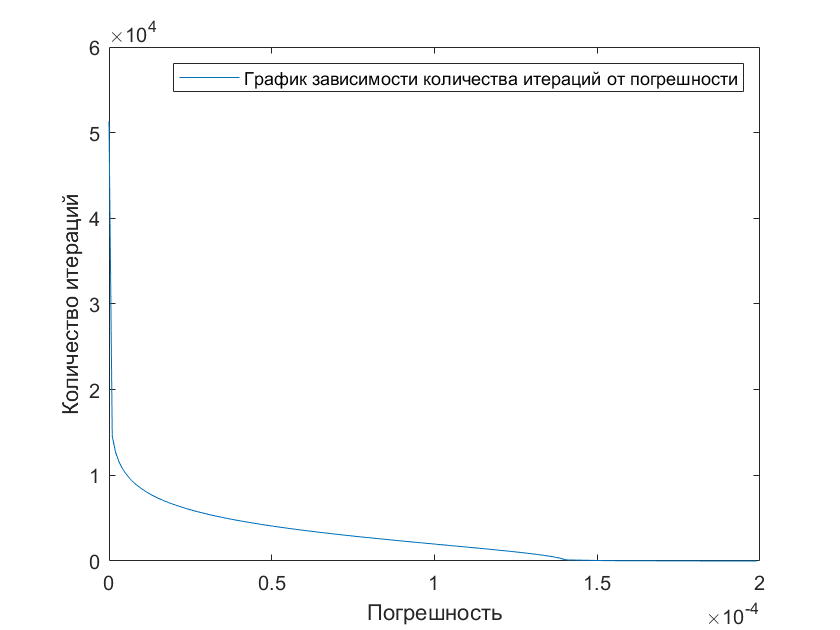

param = [0.0002,1e-12,0.000001];
 
matr = edsolve(delta2, f2, param(2), param(1), param(3), 2);
figure
plot(matr(1, :), matr(2, :))
xlabel('Погрешность');
ylabel('Количество итераций');
legend('График зависимости количества итераций от погрешности');
saveas(gcf, 'error22.png')

**Построение зависимости количества итераций от начального приближения для 2-го уравнения**

В качестве параметра начального приближения является длинна отрезка.

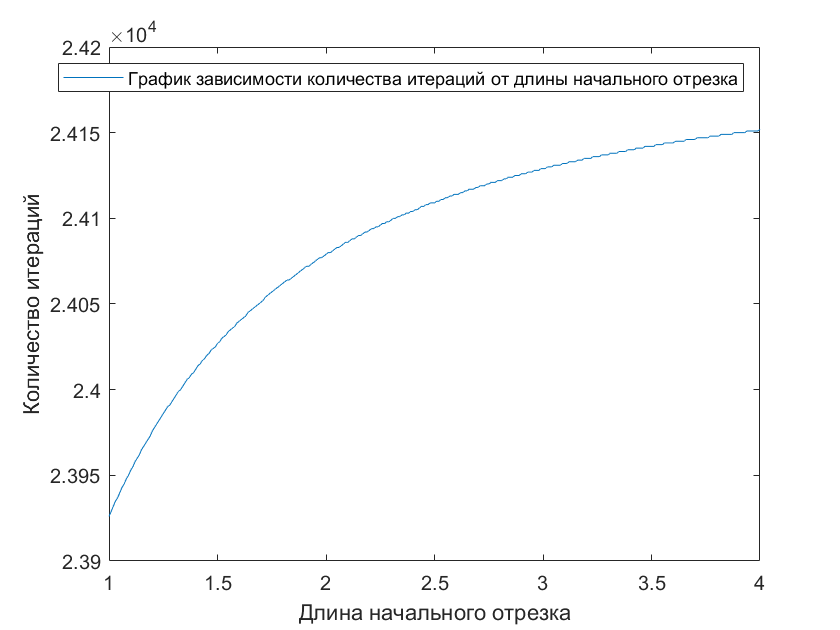

  
param = [-2,
    4,
    1,
    0.01,
    1e-12];
matr = prdsolve(param(1), f2, param(2), param(3), param(4), param(5), 2);
figure
plot(matr(1, :), matr(2, :))
xlabel('Длина начального отрезка');
ylabel('Количество итераций');
legend('График зависимости количества итераций от длины начального отрезка');
saveas(gcf, 'len22.png')

function matr_out = edsolve(ddelta, f, a, b, step, met)
E = [];
NN = [];
for e = a:step:b
    N = 0;
    for i = 1:2:length(ddelta)
        if met == 1
            lout = double_del(ddelta(i), ddelta(i+1), e, f);
        else
            lout = simple_iter(ddelta(i), e, f);
        end
        N = N + lout(1);
    end
    E = [E, e];
    NN = [NN, N];
end
matr_out = vertcat(E, NN);
end

function matr_out = prdsolve(a0, f, len_max, len_min, step, e, met)
%Функция построения зависимости количества
%итераций от начального приближения
DD = [];
NN = [];
for del = len_min:step:len_max
    if met == 1
        lout = double_del(a0-del/2, a0+del/2, e, f);
    else
        lout = simple_iter(a0-del, e, f);
    end
    DD = [DD, del];
    NN = [NN, lout(1)];
end
matr_out = vertcat(DD, NN);
end

function z = simple_iter(x0, e, f)
    syms x;
    ff = diff(f(x));
    %Максимальное количество циклов
    terminus = 10^9;
    lambda = double(0.0005*sign(subs(ff, x0)));
    x = x0 - lambda*real(f(x0));
    num = 0;
    while abs(x-x0) > e && (num < terminus)
        x0 = x;
        x = x0 - lambda*real(f(x0));
        num = num + 1;
    end
    if num == terminus
        z = [0, 0];
    else
        z = [num, x];
    end
end

function z = double_del(a, b, e, f)
%Бесит нумерация не с нуля!
num = 0;
while abs(b-a) > e
    c = (b+a)/2;
    %Добавлен переход в R для второго уравнения
    if (sign(real(f(c))) == sign(real(f(a)))) && (sign(real(f(c))) ~= sign(real(f(b))))
        a = c;
    elseif (sign(real(f(c))) == sign(real(f(b)))) && (sign(real(f(c))) ~= sign(real(f(a))))
        b = c;
    else
        c = 0;
        break
    end
    num = num + 1;
end
z = [num, c];
end